6) 

a)Aplica la técnica de igualación del histograma para mejorar la calidad de una imagen parecida  a de la figura 16(a).  

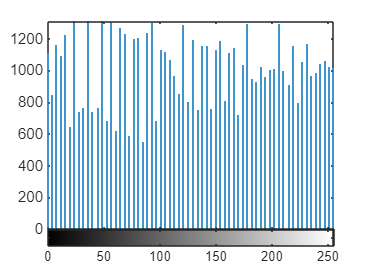

I=imread('5.1.10.tiff');  

% Igualada
figure, imhist(histeq(I)) 

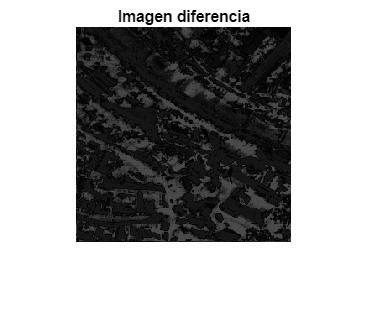

I_eq = histeq(I);

% Calcula la diferencia
I_diff = imabsdiff(I, I_eq);

figure, imshow(I_diff), title('Imagen diferencia');

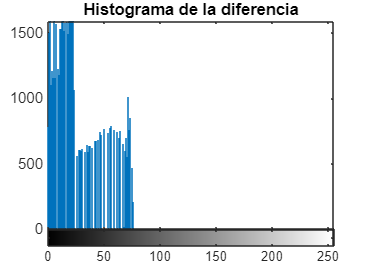

figure, imhist(I_diff), title('Histograma de la diferencia');

b)  Aplica la técnica de igualación del histograma a una imagen espacial como la de la figura 19(a)  (moon.tif). Comenta el resultado. 

I = imread('saturno.tif')

I = 328×438 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

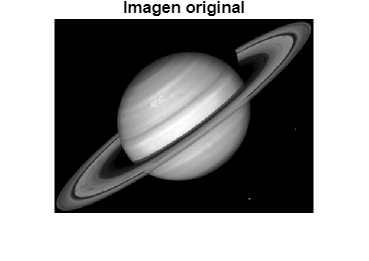

figure,imshow(I),title('Imagen original')

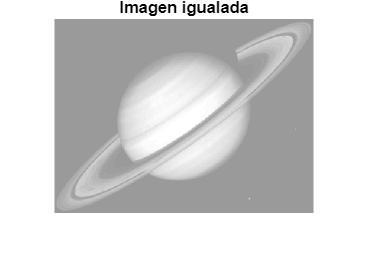

% Igualación del histograma
[I_eq, T] = histeq(I);
figure,imshow(I_eq),title('Imagen igualada')

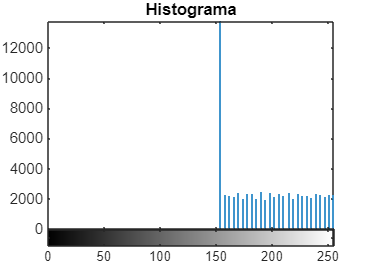

figure,imhist(I_eq),title('Histograma')

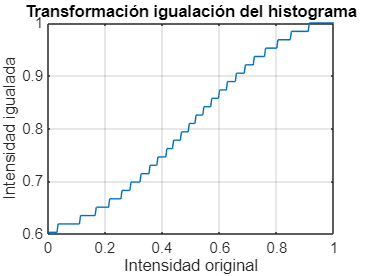


% Mostrar transformación aplicada
figure, plot((0:255)/255, T), grid on;
xlabel('Intensidad original');
ylabel('Intensidad igualada');
title('Transformación igualación del histograma');

**Resultado**: Contraste bajo en las zonas oscuras del fondo, lo cual dificultaba la apreciación de ciertos detalles. Al aplicar la igualación del histograma se ha mejorado la visibilidad en el fondo espacial, haciendo más claros los anillos y contornos del planeta. Sin embargo, parte del brillo original de Saturno se ha perdido.

7)

a) Mejora la calidad de una imagen con ruido como la de la figura 21 (a).  

% He escogido una imagen con ruido
I=imread('Fig5.08(a).jpg')

I = 448×464 uint8 matrix
     0   248   248   248   248     0   248   248   248   248   248   248   247   249   249   247   248   248   249   248   247     0   249     0   248   248   249   250   250   247   247   247     0   248   248   249   248   248   248     0   249   248   248   248   248   248   249   248   248   248
   248   248   248   247   248     0     0   248   247     0   247   248   247   249   248   249   249   248   248   248   248     0   249   248   248   248   249   249   249   247   247   247   247   247   247   248   246   248   248     0   248   248   248   248   248   247   248   248   248   248
   248   248   248   248   248   248   248     0   247   247   247   248   248   248   248   248   247   247   246   246   245   249   249   249     0   250   249   249   249   247   247   247   247   246   247   247   247   248   248   248   248   248   248   248   248     0   248   248   248   248
   248   248   248   248   248   247   247   247   247   248   249   250

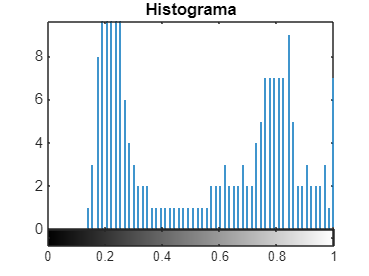

% Igualación del histograma
[J, T] = histeq(I);
figure,imhist(T),title('Histograma')

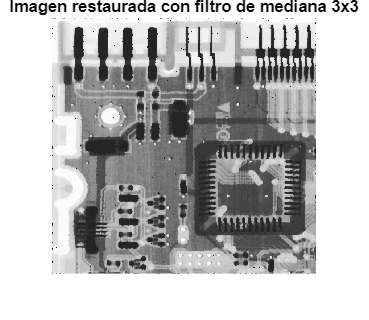

% Aplicar filtro de mediana (3x3)
I_mediana = medfilt2(J, [3 3]);
figure, imshow(I_mediana), title('Imagen restaurada con filtro de mediana 3x3');

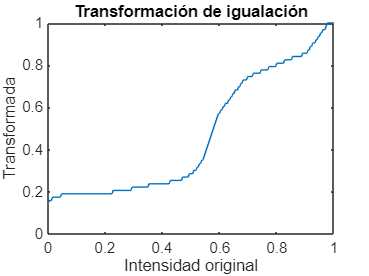


% Mostrar transformación
figure, plot((0:255)/255, T);
xlabel('Intensidad original'); ylabel('Transformada');
title('Transformación de igualación');

b) Añade ruido gaussiano a la imagen de la figura 21(a) y después restaura dicha imagen con el filtro  media y con el filtro mediana. Comenta los resultados. 

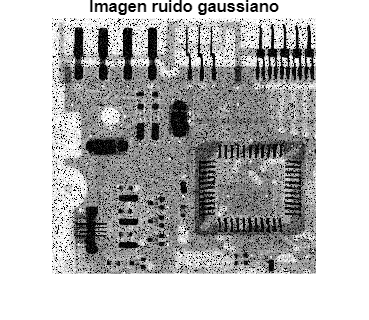

I = imread('Fig5.08(a).jpg');

% Ruido gaussiano (media = 0, varianza = 0.01)
I_gauss = imnoise(I, 'gaussian', 0, 0.01);
figure, imshow(I_gauss), title('Imagen ruido gaussiano');

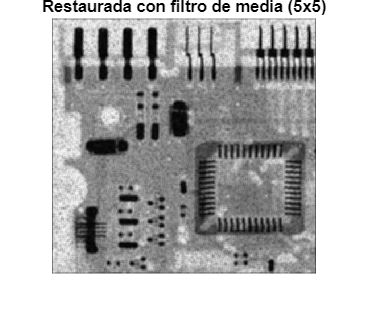


% Filtro media (ventana 5x5)
g = fspecial('average', [5 5]);
I_media = filter2(g, I_gauss)/255;  % Normalización a [0,1]
figure, imshow(I_media), title('Restaurada con filtro de media (5x5)');

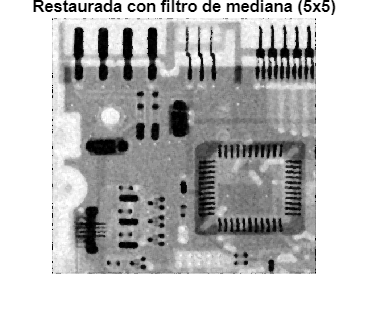


% Filtro mediana (ventana 5x5)
I_mediana = medfilt2(I_gauss, [5 5]);
figure, imshow(I_mediana), title('Restaurada con filtro de mediana (5x5)');

**Resultado**: El **filtro de mediana** preserva mejor los bordes, pero no es tan eficaz con ruido gaussiano como lo es con ruido impulsivo. En este caso, el **filtro de media** consigue un resultado más uniforme, aunque a costa de una pequeña pérdida de detalle.

**Fecha**: 08/04/2025